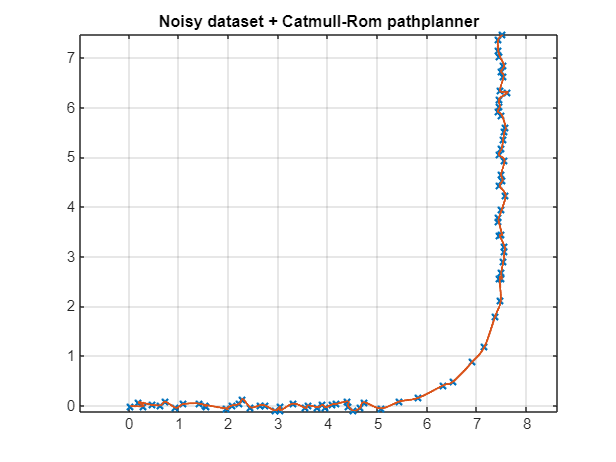

inputFileName = 'turning_path.csv';
%inputFileName = 'circle_path.csv';
%inputFileName = 'figure8_path_scaled.csv';
%inputFileName = 'turning_path_edit.csv';
opts = detectImportOptions(inputFileName);
opts = setvartype(opts, {'x', 'y'}, 'double');
coords = readtable(inputFileName, opts);
coords = table2array(coords);

% coords = ResamplePath(coords, 0.2);

% figure;
% plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
% grid on;
% axis equal;

noise_level = 0.05; % Adjust this value to control noise magnitude
coords_noisy = coords + noise_level * randn(size(coords));

plot(coords_noisy(:,1), coords_noisy(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Noisy dataset + Catmull-Rom pathplanner');
grid on;
axis equal;
hold on;
[path_x, path_y] = CatmullRomPath(coords_noisy);
plot(path_x, path_y, 'LineWidth', 1.5, 'DisplayName', 'Path');
hold off;

% figure;
% Kappa1 = LineCurvature2D([path_x(1:100:end), path_y(1:100:end)]);
% Kappa1(abs(Kappa1) > 10) = 0;
% plot(Kappa1);
% title('Curvature of noisy dataset + Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')



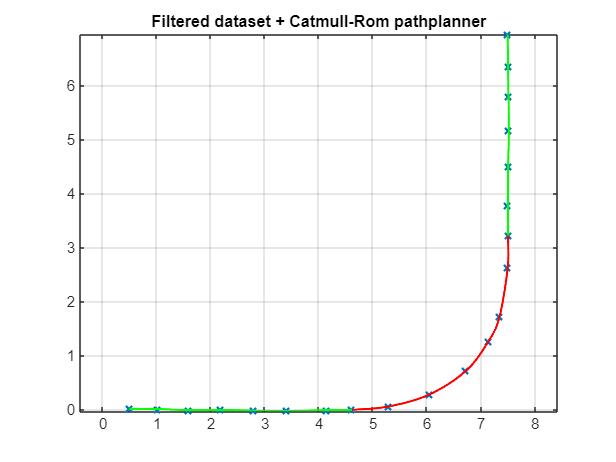

figure;
%coords = clusterAveragePerCoord(coords_noisy, 0.5);
coords = weightedCoordCluster(coords_noisy, 0.75, 1);
coords = clusterAverageCoords(coords, 0.5);
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[smooth_path_x, smooth_path_y] = CatmullRomPath([coords(:,1), coords(:,2)]);
hold off;


% figure;
% Kappa2 = LineCurvature2D([smooth_path_x(1:100:end), smooth_path_y(1:100:end)]);
% Kappa2(abs(Kappa2) > 10) = 0;
% plot(Kappa2);
% title('Curvature of Gaussian filtered dataset + Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')

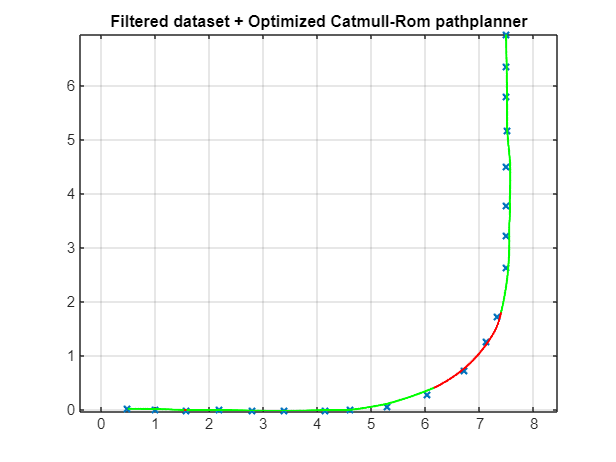

figure;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Optimized Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[altered_path_x, altered_path_y] = CatmullRomPathOptimized(coords);
hold off;


% figure;
% Kappa3 = LineCurvature2D([altered_path_x(1:100:end), altered_path_y(1:100:end)]);
% Kappa3(abs(Kappa3) > 10) = 0;
% plot(Kappa3);
% title('Curvature of Gaussian filtered dataset + Optimized Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')

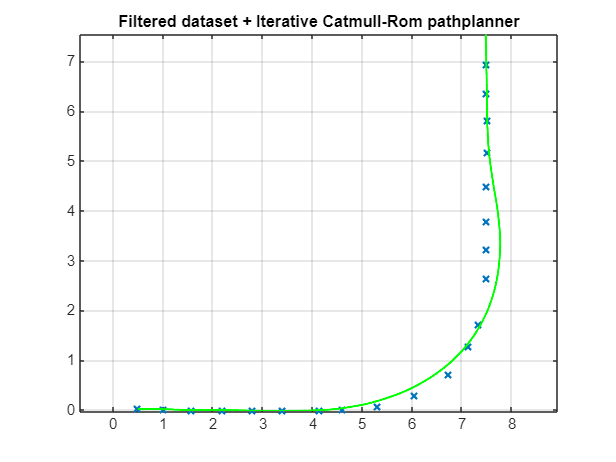

figure;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Iterative Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[path_x, path_y] = CatmullRomPathIterative(coords, 1/2.6, 50);
hold off;

figure;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Global optimization Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[path_x, path_y] = CatmullRomPathGlobal(coords, 1/2.6, 50);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          43          266.082                           931
     1         215          259.824    8.35271e-06       1.23e+03  
     2         301          229.512        5.07062       1.67e+03  
     3         344          213.953              1        1.1e+03  
     4         430            206.3       0.303783            721  
     5         473          203.236              1            558  
     6         516          200.837              1            350  
     7         559          195.259              1            543  
     8         602          192.001              1            372  
     9         645          188.188              1            675  
    10         688          185.391              1            276  
    11         731          183.187              1            300  
    12         774          179.409              

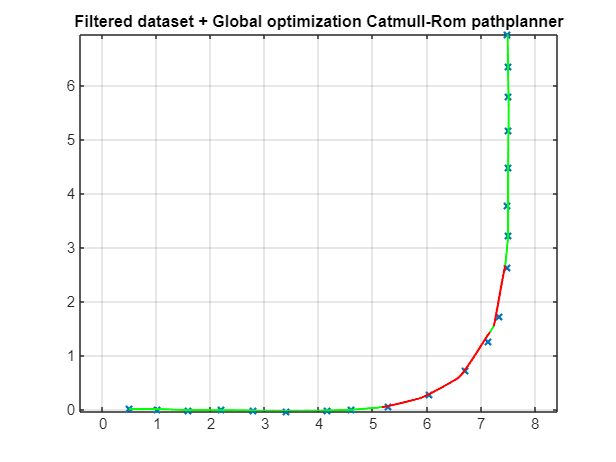

hold off;

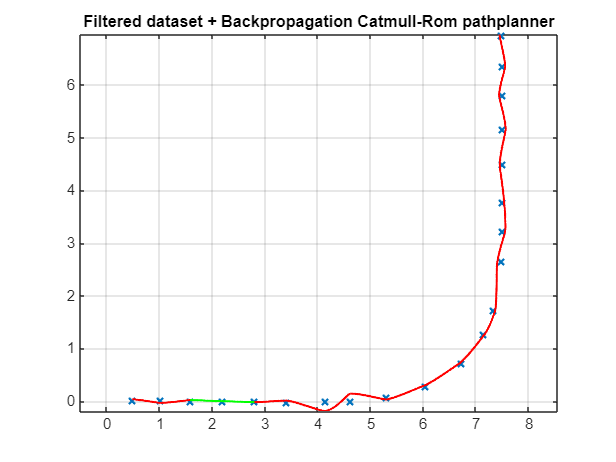

figure;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Backpropagation Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[path_x, path_y] = CatmullRomPathBackprop(coords, 1/2.6, 50, 0.0001);
hold off;


% figure;
% Kappa4 = LineCurvature2D([global_path_x(1:100:end), global_path_y(1:100:end)]);
% Kappa4(abs(Kappa4) > 10) = 0;
% plot(Kappa4);
% title('Curvature of Gaussian filtered dataset + Global Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')

% Generic Catmull-Rom functions
function [path_x, path_y] = CatmullRomPath(coords)
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points to ensure first and last points are included
    extended_coords = [2*coords(1,:) - coords(2,:);  % Extrapolated before the first point
                       coords; 
                       2*coords(end,:) - coords(end-1,:)]; % Extrapolated after the last point

    % Iterate through all segments
    for i = 2:n_points
        P0 = extended_coords(i-1, :);
        P1 = extended_coords(i, :);
        P2 = extended_coords(i+1, :);
        P3 = extended_coords(i+2, :);
        
        % Calculate Catmull-Rom segment
        catmull_rom_segment = 0.5 * (2*P1 + (-P0 + P2) .* t' + ...
                                (2*P0 - 5*P1 + 4*P2 - P3) .* (t'.^2) + ...
                                (-P0 + 3*P1 - 3*P2 + P3) .* (t'.^3));

        % Store path coordinates
        path_x = [path_x; catmull_rom_segment(:,1)];
        path_y = [path_y; catmull_rom_segment(:,2)];
        
        K = LineCurvature2D([catmull_rom_segment(:,1), catmull_rom_segment(:,2)]);
        K(abs(K) > 10) = 0;

        if any(K > 0.385)
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="red");
        else
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="green");
        end
    end
end

function [path_x, path_y] = CatmullRomPathAltered(coords)
    i = 2;
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points to ensure first and last points are included
    extended_coords = [2*coords(1,:) - coords(2,:);  % Extrapolated before the first point
                       coords; 
                       2*coords(end,:) - coords(end-1,:)]; % Extrapolated after the last point

    % Iterate through all segments
    while i < n_points + 1
        if i == 2
            P0 = extended_coords(i-1, :);
            P1 = extended_coords(i, :);
            P2 = extended_coords(i+1, :);
            P3 = extended_coords(i+2, :);
        end

        % Calculate Catmull-Rom segment
        catmull_rom_segment = catmullRomSegment(P0, P1, P2, P3, t);

        K = LineCurvature2D([catmull_rom_segment(:,1), catmull_rom_segment(:,2)]);
        K(abs(K) > 10) = 0;

        if any(K > 0.385)
            max(K)
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="red");
            [P1, P2] = curveAdjuster(P1, P2, K);
        else
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="green");
            
            % Store path coordinates
            path_x = [path_x; catmull_rom_segment(:,1)];
            path_y = [path_y; catmull_rom_segment(:,2)];
            
            P0 = P1;
            P1 = P2;
            P2 = P3;
            P3 = extended_coords(i+2, :);

            i = i+1;
        end
    end
end

function [path_x, path_y] = CatmullRomPathOptimized(coords)
    i = 2;
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points for boundary conditions
    extended_coords = [2*coords(1,:) - coords(2,:);
                       coords; 
                       2*coords(end,:) - coords(end-1,:)];

    max_curvature = 0.385;  % Constraint

    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off');

    while i < n_points + 2
        if i == 2
            P0 = extended_coords(i-1, :);
            P1 = extended_coords(i, :);
            P2 = extended_coords(i+1, :);
            P3 = extended_coords(i+2, :);
        end
        
        % P0 = extended_coords(i-1, :);
        % P1 = extended_coords(i, :);
        % P2 = extended_coords(i+1, :);
        % P3 = extended_coords(i+2, :);

        % Compute segment length for bounding
        segment_length = norm(P2 - P1);
        max_adjustment = 0.2 * segment_length;

        % Define bounds for P2 only (P1 is fixed)
        lb = P2 - max_adjustment;
        ub = P2 + max_adjustment;

        % Optimize P2 only
        P2_opt = fmincon(@(P) curvature_cost(P, P0, P1, P3, t, max_curvature), ...
                        P2, [], [], [], [], lb, ub, [], options);

        P2 = P2_opt;
        
        % Generate segment with optimized P1 and P2
        catmull_rom_segment = catmullRomSegment(P0, P1, P2, P3, t);

        % Compute curvature for visualization
        K = LineCurvature2D([catmull_rom_segment(:,1), catmull_rom_segment(:,2)]);
        K(abs(K) > 10) = 0;

        % Plot the optimized segment
        if any(abs(K) > max_curvature)
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'r', 'LineWidth', 1.5);
        else
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'g', 'LineWidth', 1.5);
        end

        % Store path
        path_x = [path_x; catmull_rom_segment(:,1)];
        path_y = [path_y; catmull_rom_segment(:,2)];

        % Shift to next segment
        P0 = P1;
        P1 = P2;
        P2 = P3;
        
        if i < n_points
            P3 = extended_coords(i+2, :);
        else
            P3 = P2; % Repeat P2 to avoid out-of-bounds error
        end

        i = i+1;
    end
end

% Iterative Catmull-Rom pathplanner
function cost = curvature_cost(P2, P0, P1, P3, t, max_curvature)
    % Generate segment with optimized P2 (keeping P1 fixed)
    segment = catmullRomSegment(P0, P1, P2, P3, t);
    
    % Compute curvature
    K = LineCurvature2D([segment(:,1), segment(:,2)]);
    K(abs(K) > 10) = 0;

    % Cost: Penalize curvature values exceeding the constraint
    cost = mean(max(0, abs(K) - max_curvature).^2);
end

function cost = gradient_curvature_cost(P2, P0, P1, P3, t, max_curvature)
    % Generate segment with optimized P2 (keeping P1 fixed)
    segment = catmullRomSegment(P0, P1, P2, P3, t);
    
    % Compute curvature
    K = LineCurvature2D([segment(:,1), segment(:,2)]);
    K(abs(K) > 10) = 0;

    % Sigmoid-based penalty
    alpha = 0.1; % Controls how steeply the penalty increases
    beta = 10; % Scaling factor to control cost magnitude
    
    penalty = 1 ./ (1 + exp(-alpha * (abs(K) - max_curvature)));
    
    % Cost: Mean penalty across all points
    cost = beta * mean(penalty);
end

function [path_x, path_y] = CatmullRomPathIterative(coords, max_curvature, max_iterations)
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points for boundary conditions
    extended_coords = [2*coords(1,:) - coords(2,:); coords; 2*coords(end,:) - coords(end-1,:)];
    
    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off');
    
    for iter = 1:max_iterations
        modified = false; % Track if any point was modified
        i = 2;
        
        while i < n_points + 2
            P0 = extended_coords(i-1, :);
            P1 = extended_coords(i, :);
            P2 = extended_coords(i+1, :);
            if i+2 <= size(extended_coords, 1)
                P3 = extended_coords(i+2, :);
            else
                P3 = extended_coords(end, :); % Laatste punt herhalen om out-of-bounds te vermijden
            end

            
            % Generate Catmull-Rom segment
            segment = catmullRomSegment(P0, P1, P2, P3, t);
            K = LineCurvature2D([segment(:,1), segment(:,2)]);
            K(abs(K) > 10) = 0;
            
            % Check if curvature exceeds max limit
            if any(abs(K) > max_curvature)
                modified = true;
                segment_length = norm(P2 - P1);
                max_adjustment = 0.1 * segment_length;
                lb = P2 - max_adjustment;
                ub = P2 + max_adjustment;
                
                % Optimize P2
                P2_opt = fmincon(@(P) curvature_cost(P, P0, P1, P3, t, max_curvature), ...
                                P2, [], [], [], [], lb, ub, [], options);
                
                % Adaptive spreading if the change is too large
                P2 = (P2 + P2_opt) / 2;
                extended_coords(i+1, :) = P2;
            end
            
            i = i + 1;
        end
        
        % Stop iterating if no modifications were made
        if ~modified
            break;
        end
    end
    
    % Generate final path
    i = 2;
    while i < n_points + 2
        P0 = extended_coords(i-1, :);
        P1 = extended_coords(i, :);
        P2 = extended_coords(i+1, :);
        if i+2 <= size(extended_coords, 1)
            P3 = extended_coords(i+2, :);
        else
            P3 = extended_coords(end, :);
        end
        
        segment = catmullRomSegment(P0, P1, P2, P3, t);
        path_x = [path_x; segment(:,1)];
        path_y = [path_y; segment(:,2)];
        
        % Compute curvature for visualization
        K = LineCurvature2D([segment(:,1), segment(:,2)]);
        K(abs(K) > 10) = 0;

        % Plot the optimized segment
        if any(abs(K) > max_curvature)
            plot(segment(:,1), segment(:,2), 'r', 'LineWidth', 1.5);
        else
            plot(segment(:,1), segment(:,2), 'g', 'LineWidth', 1.5);
        end

        i = i + 1;
    end
end

% Global Catmull-Rom pathplanner
function [optimized_path_x, optimized_path_y] = CatmullRomPathGlobal(coords, max_curvature, max_iterations)
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    
    % Voeg extra punten toe voor Catmull-Rom spline
    extended_coords = [2*coords(1,:) - coords(2,:); coords; 2*coords(end,:) - coords(end-1,:)];
    
    options = optimoptions('fminunc', 'Algorithm', 'quasi-newton', ...
    'MaxIterations', 200, 'MaxFunctionEvaluations', 10000, ...
    'OptimalityTolerance', 1e-6, 'StepTolerance', 1e-8, 'Display', 'iter');
    
    % Optimaliseer alle controlepunten tegelijk
    P_opt = fminunc(@(P) global_curvature_cost(P, extended_coords, t, max_curvature), extended_coords(2:end-1, :), options);
    
    % Genereer het geoptimaliseerde pad
    optimized_path_x = [];
    optimized_path_y = [];
    
    for i = 2:n_points
        P0 = extended_coords(i-1, :);
        P1 = P_opt(i-1, :);
        P2 = P_opt(i, :);
        P3 = extended_coords(i+1, :);
        
        segment = catmullRomSegment(P0, P1, P2, P3, t);
        optimized_path_x = [optimized_path_x; segment(:,1)];
        optimized_path_y = [optimized_path_y; segment(:,2)];

        % Compute curvature for visualization
        K = LineCurvature2D([segment(:,1), segment(:,2)]);
        K(abs(K) > 10) = 0;

        % Plot the optimized segment
        if any(abs(K) > max_curvature)
            plot(segment(:,1), segment(:,2), 'r', 'LineWidth', 1.5);
        else
            plot(segment(:,1), segment(:,2), 'g', 'LineWidth', 1.5);
        end
    end
end

function cost = global_curvature_cost(P, extended_coords, t, max_curvature)
    P = reshape(P, [], 2);  % Zet de 1D vector terug naar een Nx2 matrix
    n_points = size(P, 1);
    total_cost = 0;
    
    % Bereken de totale krommingsfout met sigmoid activatiefunctie
    for i = 2:n_points
        P0 = extended_coords(i-1, :);
        P1 = P(i-1, :);
        P2 = P(i, :);
        P3 = extended_coords(i+1, :);
        
        segment = catmullRomSegment(P0, P1, P2, P3, t);
        K = LineCurvature2D([segment(:,1), segment(:,2)]);
        K(abs(K) > 10) = 0;
        
        % Sigmoid activatiefunctie voor vloeiende kosten
        total_cost = total_cost + sum(1 ./ (1 + exp(-10 * (abs(K) - max_curvature))));
    end
    
    cost = total_cost;
end


% Backpropagation Catmull-Rom pathplanner
function [path_x, path_y] = CatmullRomPathBackprop(coords, max_curvature, max_iterations, learning_rate)
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Extend coordinates for boundary conditions
    extended_coords = [2*coords(1,:) - coords(2,:); coords; 2*coords(end,:) - coords(end-1,:)];
    P = extended_coords(2:end-1, :); % Optimize only internal points
    
    for iter = 1:max_iterations
        total_cost = curvature_cost_total(P, extended_coords, t, max_curvature);
        grad = zeros(size(P));
        
        epsilon = 1e-3; % Small perturbation for numerical gradient
        for i = 1:size(P, 1)
            for j = 1:size(P, 2)
                P_perturbed = P;
                P_perturbed(i, j) = P_perturbed(i, j) + epsilon;
                cost_perturbed = curvature_cost_total(P_perturbed, extended_coords, t, max_curvature);
                grad(i, j) = (cost_perturbed - total_cost) / epsilon;
            end
        end
        
        % Update points using gradient descent
        P = P - learning_rate * grad;
        
        % Apply learning rate decay
        learning_rate = learning_rate * 0.5;

        % Stop condition: if gradient is very small
        if norm(grad) < 1e-6
            break;
        end
    end
    
    % Generate final path
    for i = 2:n_points
        P0 = extended_coords(i-1, :);
        P1 = P(i-1, :);
        P2 = P(i, :);
        P3 = extended_coords(i+1, :);
        segment = catmullRomSegment(P0, P1, P2, P3, t);
        path_x = [path_x; segment(:,1)];
        path_y = [path_y; segment(:,2)];
        
        % Compute curvature for visualization
        K = LineCurvature2D([segment(:,1), segment(:,2)]);
        K(abs(K) > 10) = 0;

        % Plot the optimized segment
        if any(abs(K) > max_curvature)
            plot(segment(:,1), segment(:,2), 'r', 'LineWidth', 1.5);
        else
            plot(segment(:,1), segment(:,2), 'g', 'LineWidth', 1.5);
        end
    end
end

function cost = curvature_cost_total(P, extended_coords, t, max_curvature)
    cost = 0;
    
    P_full = [extended_coords(1, :); P; extended_coords(end, :)];
    for i = 2:size(P_full, 1) - 2
        P0 = P_full(i-1, :);
        P1 = P_full(i, :);
        P2 = P_full(i+1, :);
        P3 = P_full(i+2, :);
        segment = catmullRomSegment(P0, P1, P2, P3, t);
        K = LineCurvature2D([segment(:,1), segment(:,2)]);
        K(abs(K) > 10) = 0;
        
        % Use smooth penalty function
        cost = cost + sum(sigmoid_penalty(K, max_curvature));
    end
end

function penalty = sigmoid_penalty(K, max_curvature)
    beta = 10; % Sharpness of sigmoid
    penalty = 1 ./ (1 + exp(-beta * (abs(K) - max_curvature)));
end

function segment = catmullRomSegment(P0, P1, P2, P3, t)
    segment = 0.5 * (2*P1 + (-P0 + P2) .* t' + (2*P0 - 5*P1 + 4*P2 - P3) .* (t'.^2) + (-P0 + 3*P1 - 3*P2 + P3) .* (t'.^3));
end

function resampled_coords = ResamplePath(coords, d_spacing)
    % Compute cumulative distance along the original path
    distances = [0; cumsum(sqrt(sum(diff(coords).^2, 2)))];  
    total_length = distances(end);

    % Determine number of points based on desired spacing
    num_points = round(total_length / d_spacing);

    % Generate new interpolated distances
    new_distances = linspace(0, total_length, num_points);

    % Interpolate new x and y coordinates
    resampled_x = interp1(distances, coords(:,1), new_distances, 'linear');
    resampled_y = interp1(distances, coords(:,2), new_distances, 'linear');

    % Combine into output array
    resampled_coords = [resampled_x', resampled_y'];
end

function filtered_coords = preprocessCoords(coords, threshold)
    % Reduce noise by clustering close points and selecting representative ones
    filtered_coords = coords(1, :); % Initialize with the first point
    
    for i = 2:size(coords, 1)
        % Calculate the distance to the last filtered point
        dist = norm(coords(i, :) - filtered_coords(end, :));
        
        if dist > threshold
            filtered_coords = [filtered_coords; coords(i, :)]; % Add point if far enough
        end
    end
end

function filtered_coords = clusterAverageCoords(coords, threshold)
    % Initialize filtered coordinates with the first point
    filtered_coords = coords(1, :);
    temp_cluster = coords(1, :); % Temporary cluster for averaging

    for i = 2:size(coords, 1)
        % Compute distance to last stored point
        dist = norm(coords(i, :) - filtered_coords(end, :));

        if dist < threshold
            % Add to temporary cluster (points within threshold)
            temp_cluster = [temp_cluster; coords(i, :)];
        else
            % Compute cluster centroid (average)
            filtered_coords(end, :) = mean(temp_cluster, 1);
            
            % Start a new cluster
            temp_cluster = coords(i, :);
            filtered_coords = [filtered_coords; coords(i, :)];
        end
    end

    % Ensure last cluster is averaged
    filtered_coords(end, :) = mean(temp_cluster, 1);
end

function filtered_coords = clusterAveragePerCoord(coords, threshold)
    filtered_coords = zeros(size(coords));

    for i = 1:size(coords, 1)
        % Look at the next 10 points or until the end of the path
        max_lookahead = min(i + 10, size(coords, 1));
        lookahead_coords = coords(1:max_lookahead, :);
        
        distances = vecnorm(lookahead_coords - coords(i, :), 2, 2);
        
        cluster_indices = distances < threshold;
        filtered_coords(i, :) = mean(lookahead_coords(cluster_indices, :), 1);
    end
end

 
function filtered_coords = weightedCoordCluster(coords, threshold, sigma)
    filtered_coords = zeros(size(coords));

    for i = 1:size(coords, 1)
        max_lookahead = min(i + 10, size(coords, 1));
        lookahead_coords = coords(1:max_lookahead, :);
        
        % Calculate distances to all points in the lookahead window
        distances = vecnorm(lookahead_coords - coords(i, :), 2, 2);
        
        % Apply the Gaussian weight function: w(x) = exp(-x^2 / (2 * sigma^2))
        weights = exp(-distances.^2 / (2 * sigma^2));
        
        % Only keep points within the threshold distance
        valid_indices = distances < threshold;
        
        % Normalize weights for the selected valid points
        weighted_coords = bsxfun(@times, lookahead_coords(valid_indices, :), weights(valid_indices) / sum(weights(valid_indices)));
        
        % Calculate the weighted average of the valid points
        filtered_coords(i, :) = sum(weighted_coords, 1);
    end
end
